## Example: FGL 3-Bus test system: Admitance matrix

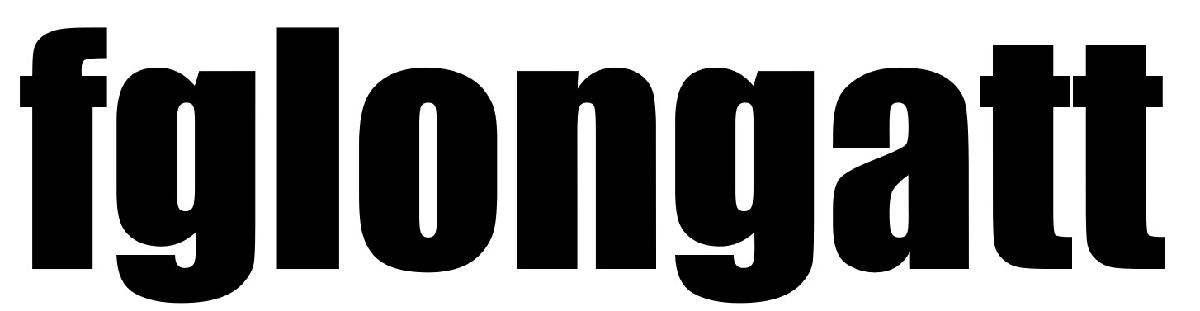  Prof F Gonzalez-Longatt, [fglongatt@fglongatt.org](http://fglongatt@fglongatt.org) 

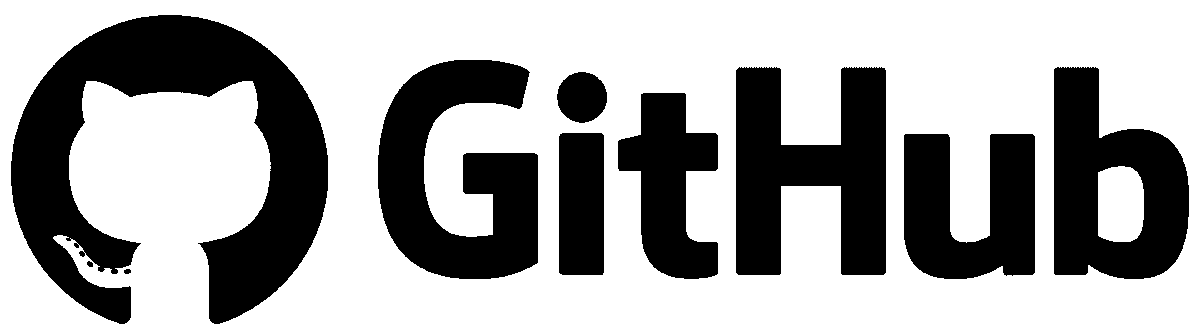 [https://github.com/fglongatt](https://github.com/fglongatt) 

Considers the **FGL 3-bus test system** shown in Figure 1.

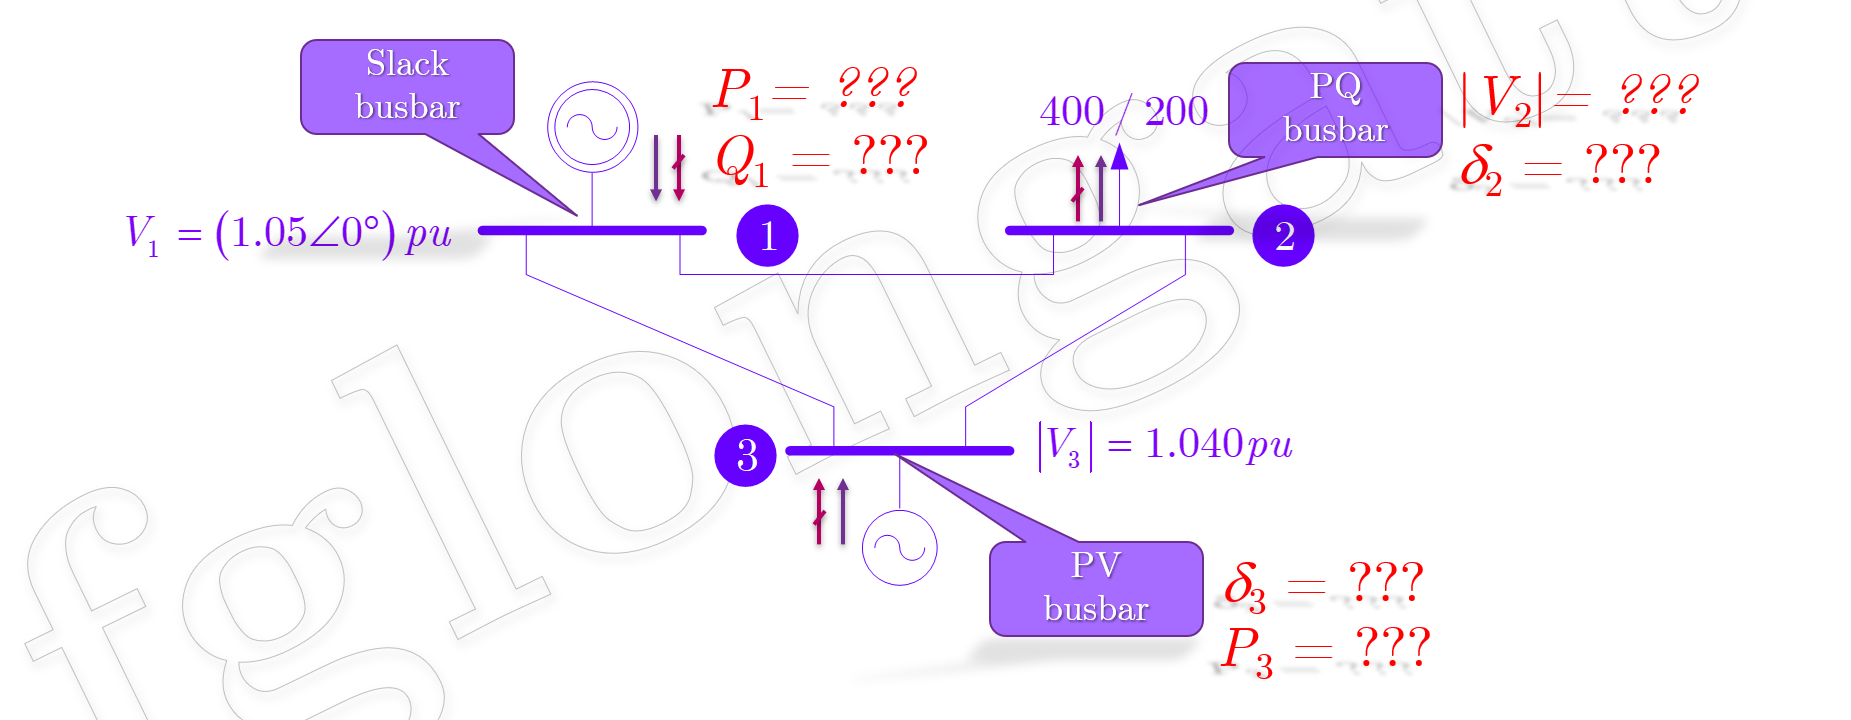

**Figure 1.** Single-line diagram of FGL 3-bus test system.

The system data is presented below.

### BUS DATA                               

Bus          Voltage(KV)   Load(MW)    Load(MVAR)      

----------------------------------------------------------------------------

BUS_1           115.0            0.00       0.00

BUS_2           115.0         400.00      200.00

BUS_3           115.0           0.00       0.00

### BRANCH DATA

From Bus    To Bus         MVA      Long(Km) r(Ω/km)  x(Ω/km)   g(us/km)   b(nF/km)

----------------------------------------------------------------------------------------------

BUS_1      BUS_2          100.0       1.0       2.645      5.290      0.000      0.000

BUS_1      BUS_3          100.0       1.0       1.322      3.967      0.000      0.000

BUS_2      BUS_3          100.0       1.0       1.653      3.306      0.000      0.000

Consider $\;S_{\textrm{base}} =100\textrm{MVA}$ and $V_{\textrm{base}} =115\;\;\textrm{kV}$ 

Build the netwok model using the admittance matrix (**Ybus**).

### Solution

clc         % clc clears all the text from the Command Window
clearvars   % clearvars removes all variables from the currently active workspace

The indiviual elements of the admittance matrix (**Y****bus**) {*Yij*} are defined in terms of the physical admittances  {*y**ij*} as:

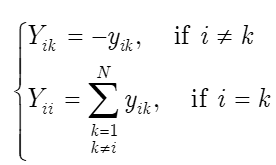     Equation (1)

The FGL 3-Bus test system has only three buses: *N* = 3, so the admitance matrix (**Ybus**) results in a square matrix 3x3:

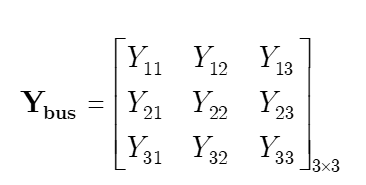    Equation (2)

The solution is obatined by numerically obtaining the elements of the admittance matrix  {*yij*} using the Equation (2).

The system electrical data (*R* and *X*) data is provided in real units (Ω) as:

% Index: From_Bus to To_Bus
% Series resistance R(Ω), 1km is assumed
R(1,2) = 2.645;
R(1,3) = 1.322;
R(2,3) = 1.653;
% Series Reactance X(Ω), 1km is assumed
X(1,2) = 5.29;
X(1,3) = 3.967;
X(2,3) = 3.306;

The ystem electrical data (*R* and *X*) data can be refered to the per unit system considering the following bases:

Vbase = 115e3;       % Vbase: Base voltage in Volts
Sbase = 100e6;       % Sbase: Apparant base power in VA

Calculating the impedance base ($Z_{\textrm{base}}$ in Ω):

$Z_{\textrm{base}} =\frac{V_{\textrm{base}}^2 }{S_{\textrm{base}} }$            Equation (3)

% Using Equation (3)
Zbase = Vbase^2/Sbase;
fprintf(' Zbase =%4.4f Ω',Zbase)

 Zbase =132.2500 Ω

Converting the resistance (*R*) and reactances (*X*) into per unit values:

$Z\left\lbrack \textrm{pu}\right\rbrack =\frac{Z\left\lbrack \Omega \right\rbrack }{Z_{\textrm{base}} \left\lbrack \Omega \right\rbrack }$          Equation (4)

fprintf( ' Resistance and Reactance in per unit value: ')

 Resistance and Reactance in per unit value: 

fprintf( ' -------------------------------------- ')

 -------------------------------------- 

R = R/Zbase

R =          0    0.0200    0.0100
         0         0    0.0125


X = X/Zbase

X =          0    0.0400    0.0300
         0         0    0.0250


## Built the admitance matrix (Ybus)

### Case 1: Network Purely reactive (*R* = 0)

Considering the transmission system **purely reactive, *****R***** = 0:**

% Calculating the series impedance Z = R + i * X
Z(1,2) = + 1i*X(1,2);
Z(1,3) = + 1i*X(1,3);
Z(2,3) = + 1i*X(2,3);
% Calculating the individual terms of the admitance matrix (Ybus)
% using Equation (1)
y(1,1) = 1 / Z(1,2) + 1 / Z(1,3);
y(2,2) = 1 / Z(1,2) + 1 / Z(2,3);
y(3,3) = 1 / Z(1,3) + 1 / Z(2,3);
y(1,2) = -1 / Z(1,2);
y(1,3) = -1 / Z(1,3);
y(2,3) = -1 / Z(2,3);
y(2,1) = y(1,2);
y(3,2) = y(2,3);
y(3,1) = y(1,3);
fprintf(' Admitance Matrix: Purely inductive, Asummed R = 0')

 Admitance Matrix: Purely inductive, Asummed R = 0

fprintf(' -------------------------------------------')

 -------------------------------------------

y

y =    0.0000 -58.3375i   0.0000 +25.0000i   0.0000 +33.3375i
   0.0000 +25.0000i   0.0000 -65.0030i   0.0000 +40.0030i
   0.0000 +33.3375i   0.0000 +40.0030i   0.0000 -73.3406i


### Case 2: Network considering resistance (*Z* = *R* + *i***X*)

Considering the transmission system resistive and inductive:

% Calculating the series impedance Z = R + i * X
Z(1,2) = R(1,2) + 1i*X(1,2);
Z(1,3) = R(1,3) + 1i*X(1,3);
Z(2,3) = R(2,3) + 1i*X(2,3);
% Calculating the individual terms of the admitance matrix (Ybus)
% using Equation (3)
Y(1,1) = 1 / Z(1,2) + 1 / Z(1,3);
Y(2,2) = 1 / Z(1,2) + 1 / Z(2,3);
Y(3,3) = 1 / Z(1,3) + 1 / Z(2,3);
Y(1,2) = -1 / Z(1,2);
Y(1,3) = -1 / Z(1,3);
Y(2,3) = -1 / Z(2,3);
Y(2,1) = Y(1,2);
Y(3,2) = Y(2,3);
Y(3,1) = Y(1,3);
fprintf(' Admitance Matrix: Y =  G - i * B')

 Admitance Matrix: Y =  G - i * B

fprintf(' -------------------------------------------')

 -------------------------------------------

Y

Y =   19.9992 -50.0053i -10.0000 +20.0000i  -9.9992 +30.0053i
 -10.0000 +20.0000i  26.0012 -52.0024i -16.0012 +32.0024i
  -9.9992 +30.0053i -16.0012 +32.0024i  26.0005 -62.0077i


### Comparing Case 2 with the respulsts from PowerWorld software:

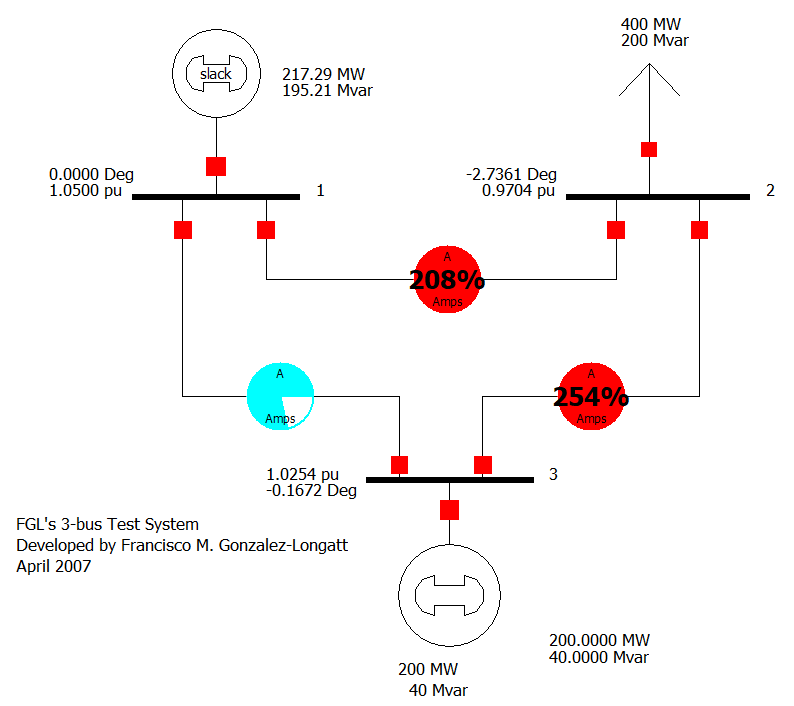

**File:** FGL_3-bus_TestSystem.pwb

The numerical values of the admittance matrix obtained by using PowerWorld software.

### 

### Interesting aspect to consider when modeling system matrixes for DC load flow


$$\mathbf{Y}=\mathbf{G}-\textrm{jB}$$
 


$$\mathbf{B}=-\textrm{imag}\left(\mathbf{Y}\right)$$


fprintf(' Y = G - i* B')

 Y = G - i* B

fprintf(' Suceptance Matrix: B = imag(Y)')

 Suceptance Matrix: B = imag(Y)

fprintf(' -------------------------------------------')

 -------------------------------------------

B = -imag(Y)

B =    50.0053  -20.0000  -30.0053
  -20.0000   52.0024  -32.0024
  -30.0053  -32.0024   62.0077
